%%Clase 1 - Introducción al MEF con cálculo matricial.
% Parámetros del problema %
nu=1/3; E=2E5; L=1; rext = L/20; P=1E4; t=L/200; 
A = pi * (rext^2 - t^2)

A = 0.0078

% Variables a reutilizar en el problema en la matriz de rigidez - eficiencia cálculo
I = pi/4*(rext^4 - (rext-t)^4);
e_a_l = E*A/L;
e_i_l = E*I/L;
e_i_l2 = e_i_l/L;
e_i_l3 = e_i_l2/L;
% Coordenadas de los nodos
n1 = [0, L/2];
n2 = [0, 0];
n3 = [0, -L];
n4 = [L, 0];

Cálculo de matrices de rigidez por elemento en coordenadas globales. Resolvemos usando vigas

%% Elemento 2

Le2 = L;
alpha2 = 0;
Re2 = [cos(alpha2) sin(alpha2) 0; -sin(alpha2) cos(alpha2) 0; 0 0 1]; %%Matriz de rotación de tres grados de libertad = 1 nodo x->x'
Re2_ = [Re2 zeros(3);zeros(3) Re2]; %%Matriz de rotación total, correspondiente a seis grados de libertad = 2 nodos

Ke2 = [e_a_l 0 0 -e_a_l 0 0;0 12*e_i_l3 6*e_i_l2 0 -12*e_i_l3 6*e_i_l2;0 6*e_i_l2 4*e_i_l 0 -6*e_i_l2 2*e_i_l;-e_a_l 0 0 e_a_l 0 0;0 -12*e_i_l3 -6*e_i_l2 0 12*e_i_l3 -6*e_i_l2;0 6*e_i_l2 2*e_i_l 0 -6*e_i_l2 4*e_i_l]

Ke2 = 1.0e+03 *

    1.5551         0         0   -1.5551         0         0
         0    0.0041    0.0020         0   -0.0041    0.0020
         0    0.0020    0.0014         0   -0.0020    0.0007
   -1.5551         0         0    1.5551         0         0
         0   -0.0041   -0.0020         0    0.0041   -0.0020
         0    0.0020    0.0007         0   -0.0020    0.0014


Ke2_ = Re2_' * Ke2 * Re2_

Ke2_ = 1.0e+03 *

    1.5551         0         0   -1.5551         0         0
         0    0.0041    0.0020         0   -0.0041    0.0020
         0    0.0020    0.0014         0   -0.0020    0.0007
   -1.5551         0         0    1.5551         0         0
         0   -0.0041   -0.0020         0    0.0041   -0.0020
         0    0.0020    0.0007         0   -0.0020    0.0014




%% Elemento 1

Le1 = sqrt(n1(2)^2 + n4(1)^2);
e_a_l = E*A/Le1;
e_i_l = E*I/Le1;
e_i_l2 = e_i_l/Le1;
e_i_l3 = e_i_l2/Le1;

alpha1 = -atan(n1(2)/n4(1));
Re1 = [cos(alpha1) sin(alpha1) 0; -sin(alpha1) cos(alpha1) 0; 0 0 1]; %%Matriz de rotación de tres grados de libertad = 1 nodo
Re1_ = [Re1 zeros(3);zeros(3) Re1]; %%Matriz de rotación total, correspondiente a 6 grados de libertad = 2 nodos

Ke1 = [e_a_l 0 0 -e_a_l 0 0;0 12*e_i_l3 6*e_i_l2 0 -12*e_i_l3 6*e_i_l2;0 6*e_i_l2 4*e_i_l 0 -6*e_i_l2 2*e_i_l;-e_a_l 0 0 e_a_l 0 0;0 -12*e_i_l3 -6*e_i_l2 0 12*e_i_l3 -6*e_i_l2;0 6*e_i_l2 2*e_i_l 0 -6*e_i_l2 4*e_i_l]

Ke1 = 1.0e+03 *

    1.3909         0         0   -1.3909         0         0
         0    0.0029    0.0016         0   -0.0029    0.0016
         0    0.0016    0.0012         0   -0.0016    0.0006
   -1.3909         0         0    1.3909         0         0
         0   -0.0029   -0.0016         0    0.0029   -0.0016
         0    0.0016    0.0006         0   -0.0016    0.0012


Ke1_ = Re1_' * Ke1 * Re1_

Ke1_ = 1.0e+03 *

    1.1133   -0.5552    0.0007   -1.1133    0.5552    0.0007
   -0.5552    0.2805    0.0014    0.5552   -0.2805    0.0014
    0.0007    0.0014    0.0012   -0.0007   -0.0014    0.0006
   -1.1133    0.5552   -0.0007    1.1133   -0.5552   -0.0007
    0.5552   -0.2805   -0.0014   -0.5552    0.2805   -0.0014
    0.0007    0.0014    0.0006   -0.0007   -0.0014    0.0012




%% Elemento 3

Le3 = sqrt(n3(2)^2 + n4(1)^2);
e_a_l = E*A/Le3;
e_i_l = E*I/Le3;
e_i_l2 = e_i_l/Le3;
e_i_l3 = e_i_l2/Le3;

alpha3 = atan(-n3(2)/n4(1));
Re3 = [cos(alpha3) sin(alpha3) 0; -sin(alpha3) cos(alpha3) 0; 0 0 1]; %%Matriz de rotación de tres grados de libertad = 1 nodo
Re3_ = [Re3 zeros(3);zeros(3) Re3]; %%Matriz de rotación total, correspondiente a cuatro grados de libertad = 2 nodos

Ke3 = [e_a_l 0 0 -e_a_l 0 0;0 12*e_i_l3 6*e_i_l2 0 -12*e_i_l3 6*e_i_l2;0 6*e_i_l2 4*e_i_l 0 -6*e_i_l2 2*e_i_l;-e_a_l 0 0 e_a_l 0 0;0 -12*e_i_l3 -6*e_i_l2 0 12*e_i_l3 -6*e_i_l2;0 6*e_i_l2 2*e_i_l 0 -6*e_i_l2 4*e_i_l]

Ke3 = 1.0e+03 *

    1.0996         0         0   -1.0996         0         0
         0    0.0014    0.0010         0   -0.0014    0.0010
         0    0.0010    0.0010         0   -0.0010    0.0005
   -1.0996         0         0    1.0996         0         0
         0   -0.0014   -0.0010         0    0.0014   -0.0010
         0    0.0010    0.0005         0   -0.0010    0.0010


Ke3_ = Re3_' * Ke3 * Re3_

Ke3_ =   550.5230  549.0906   -0.7162 -550.5230 -549.0906   -0.7162
  549.0906  550.5230    0.7162 -549.0906 -550.5230    0.7162
   -0.7162    0.7162    0.9549    0.7162   -0.7162    0.4775
 -550.5230 -549.0906    0.7162  550.5230  549.0906    0.7162
 -549.0906 -550.5230   -0.7162  549.0906  550.5230   -0.7162
   -0.7162    0.7162    0.4775    0.7162   -0.7162    0.9549


## Ensamblaje de elementos

gdl_e1 = [1 2 3 13 14 4]; %%grados de libertad de e1
gdl_e2 = [5 6 7 13 14 8]; %%grados de libertad de e2
gdl_e3 = [9 10 11 13 14 12]; %%grados de libertad de e3

K = zeros(14); %%declaración de matriz de rigidez de la estructura vacía

K(gdl_e1,gdl_e1) = K(gdl_e1,gdl_e1) + Ke1_; %%ensamblaje de e1 en la estructura en coordenadas globales.
K(gdl_e2,gdl_e2) = K(gdl_e2,gdl_e2) + Ke2_; %%ensamblaje de e2 en la estructura en coordenadas globales.
K(gdl_e3,gdl_e3) = K(gdl_e3,gdl_e3) + Ke3_; %%ensamblaje de e3 en la estructura en coordenadas globales.

K %%Matriz de rigidz completa en globales

K = 1.0e+03 *

    1.1133   -0.5552    0.0007    0.0007         0         0         0         0         0         0         0         0   -1.1133    0.5552
   -0.5552    0.2805    0.0014    0.0014         0         0         0         0         0         0         0         0    0.5552   -0.2805
    0.0007    0.0014    0.0012    0.0006         0         0         0         0         0         0         0         0   -0.0007   -0.0014
    0.0007    0.0014    0.0006    0.0012         0         0         0         0         0         0         0         0   -0.0007   -0.0014
         0         0         0         0    1.5551         0         0         0         0         0         0         0   -1.5551         0
         0         0         0         0         0    0.0041    0.0020    0.0020         0         0         0         0         0   -0.0041
         0         0         0         0         0    0.0020    0.0014    0.0007         0         0         0         0         0   -0.002

## Condensación de matrices para imponer C.C.


gdl = [1:14]; %% 3 nodos con grados de libertad en x,y, theta y uno x,y
gdl_r = [1:12]; %%grados de libertad correspondientes a desplazamientos restringidos
gdl_l = setdiff(gdl, gdl_r); %%grados de libertad corespondientes a desplazamientos libres

Kll = K(gdl_l,gdl_l); %%Extraigo los elementos  correspondientes a grados libres.
Krl = K(gdl_r, gdl_l); %%Extraigo los elementos correspondientes a acoplamiento de grados restringidos/libres

%%%%
%% Inicio el cálculo de ul - mediante la expresion fl = Kll * ul + Klr * ur
%%%%
feq = zeros(14,1); %% Declaración de vector de fuerzas
gamma = pi/4;
fl = P*[cos(gamma);-sin(gamma)]

fl = 1.0e+03 *

    7.0711
   -7.0711


feq(gdl_l) = feq(gdl_l) + fl;
ul = Kll\fl %%Slash == inversión Kll Desplazamientos en nodo 4

ul =     2.1807
   -8.4516



%%%%
%% Paso ahora a calcular fuerzas mediante la expresión fr = Krr * ur + Krl * ul
%%%%
u = zeros(14,1); %vector de desplazamientos vacío
u(gdl_l) = u(gdl_l) + ul;
fr = Krl * ul;  %%fuerzas en grados restringidos:reacción
feq(gdl_r) = feq(gdl_r) + fr 

feq = 1.0e+03 *

   -7.1201
    3.5814
    0.0107
    0.0107
   -3.3911
    0.0342
    0.0171
    0.0171
    3.4402
    3.4554


## Representación

%%representación
axis equal
title('Estructura original y deformada elástica','FontSize',10);
xlabel('Posiciones nodales X','FontSize',10);
ylabel('Posiciones nodales Y','FontSize',10);
cnodos = [n1; n2; n3; n4];
escala = 0.25 * max(max(abs(cnodos)))/max(abs(u));
 
figure(1)
clf
hold on
%%represento elemento 1
plot([n1(1,1) n4(1,1)], [n1(1,2) n4(1,2)],'-bo')
%%represento elemento 1 deformado
ue1 = u(gdl_e1)

ue1 =          0
         0
         0
    2.1807
   -8.4516
         0


plot([n1(1,1) + ue1(1) * escala     n4(1,1) + ue1(4) * escala], [n1(1,2) + ue1(2) * escala  n4(1,2) + ue1(5) * escala ],'--r')

%%elemento 2
plot([n2(1,1) n4(1,1)], [n2(1,2) n4(1,2)],'-bo')
%%represento elemento 2 deformado
ue2 = u(gdl_e2)

ue2 =          0
         0
         0
    2.1807
   -8.4516
         0


plot([n2(1,1) + ue2(1) * escala     n4(1,1) + ue2(4) * escala], [n2(1,2) + ue2(2) * escala  n4(1,2) + ue2(5) * escala ],'--r')

%%elemento 3
plot([n3(1,1) n4(1,1)], [n3(1,2) n4(1,2)],'-bo')
%%represento elemento 3 deformado
ue3 = u(gdl_e3)

ue3 =          0
         0
         0
    2.1807
   -8.4516
         0


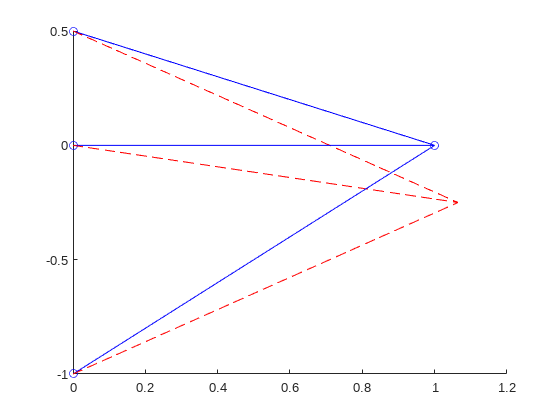

plot([n3(1,1) + ue3(1) * escala     n4(1,1) + ue1(4) * escala], [n3(1,2) + ue3(2) * escala  n4(1,2) + ue3(5) * escala ],'--r')